# 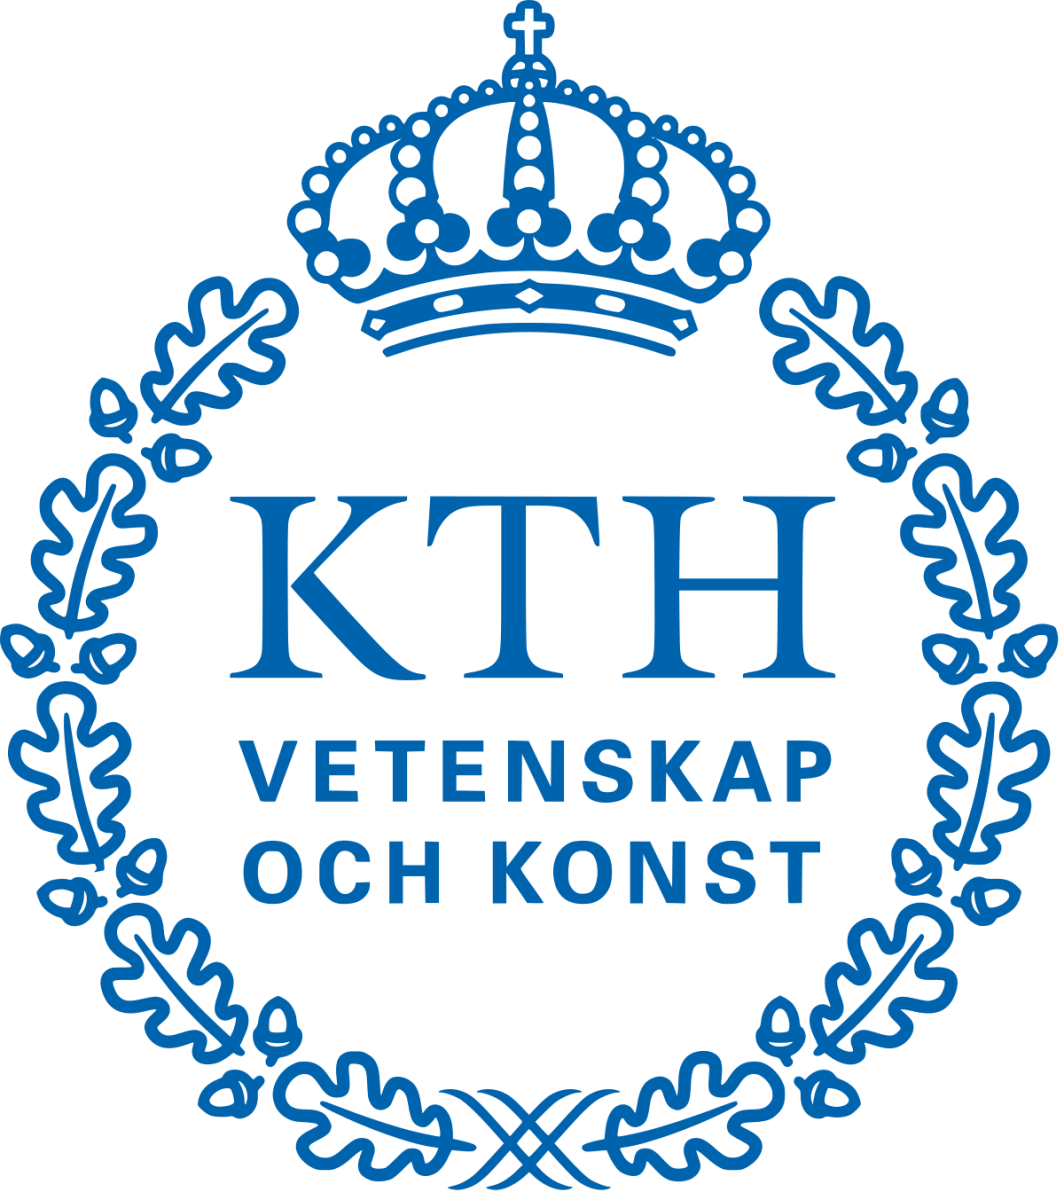

# SD2125 Signals and Mechanical Systems

# HOME ASSIGNMENT 1 (HA1)

# STUDENT 1 Marcus von Post Carlsson

# STUDENT 2 Spencer Karlström Huerta

In this assignment you are intended to learn some basic concepts in signal analysis and how to use these functions in MATLAB with. The assignment is divided into four sections: (1) time histories and signal descriptors, (2) convolution, (3) discrete signals in time domain, and (4) correlation. The assignment is intended to be in pairs, but it is also fine to do it alone (in that case, please remove the STUDENT 2 line). 

The product help under the help menu in MATLAB is recommended to use when understanding what predefined functions are suitable to implement. Pay special attention to how MATLAB outputs are organized. The following toolboxes are required: Signal Processing, Statistics & Curve fitting. Pay special attention to how MATLAB outputs are organized. It is recommended to "Run Section" instead of "Run" (the whole code) to prevent unnecessary code runs. 

# INSTRUCTIONS FOR ASSIGNMENT AND REPORT

In this Live Script, you will find **empty CODE slots **where you must fill in relevant codes and **empty ANSWER slots **where you must fill in answers to given questions. The structure of the Live Script should not be modified, that is, **do not change/remove headings, numberings, or sections—even if you submit blank in any of them**. Make sure you also add your name(s) at the top of this document (here). If you did the assignment alone, add your name in Student 1 and delete the row for Student 2. 

Once you are finished with your assignment, you should produce a PDF report out of the Live Script. No introduction, discussion nor conclusion are required in the report, only answer the questions and show the plots as instructed. You can produce the PDF report by clicking `"Save As..."` and selecting **PDF (*.pdf)** format. 

**OBS**: **Make sure you save the PDF file including the name(s) of the student(s) who did the work: HA1_Initial-Surname_Initial-Surname, for example: "**`HA1_K-Bolin_E-Zea.pdf`**".  **

# 1: TIME HISTORIES AND SIGNAL DESCRIPTION

## 1.1 Read wav files and classify signals

In this task, you will read wav files from the workspace and classify four kinds of signals into periodic, random, transient, deterministic. 

### 1.1.1.     Read wav files Sound1 - Sound4 into MATLAB 

Use the function “`audioread`” and the help desk to get the signal time series, sampling frequency.

% add your code here
[y, Fs] = audioread("Sound1.wav");

### 1.1.2.     Classify the signals in terms of: Periodic, random, transient, deterministic by plotting them and examining them by zooming and unzooming the graphs 

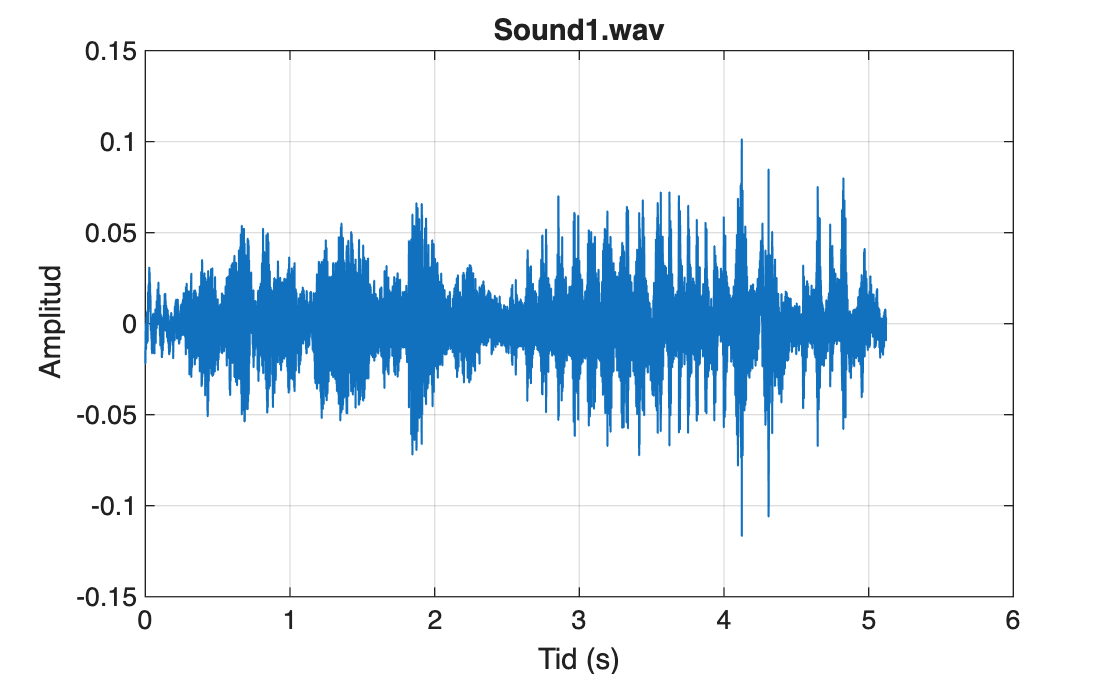

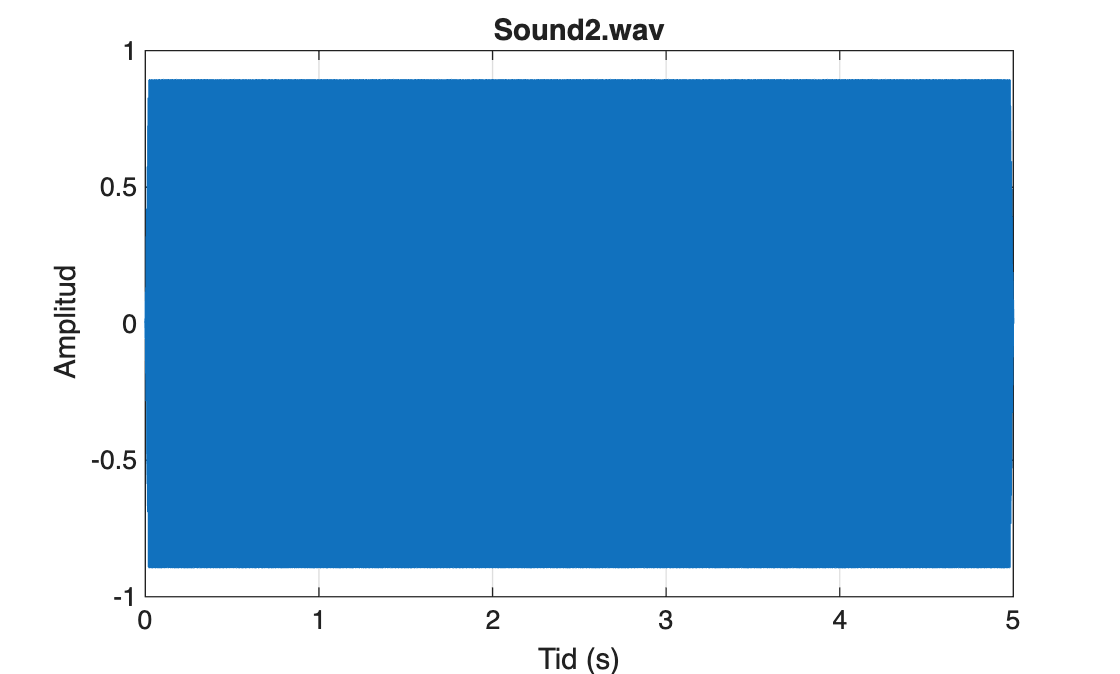

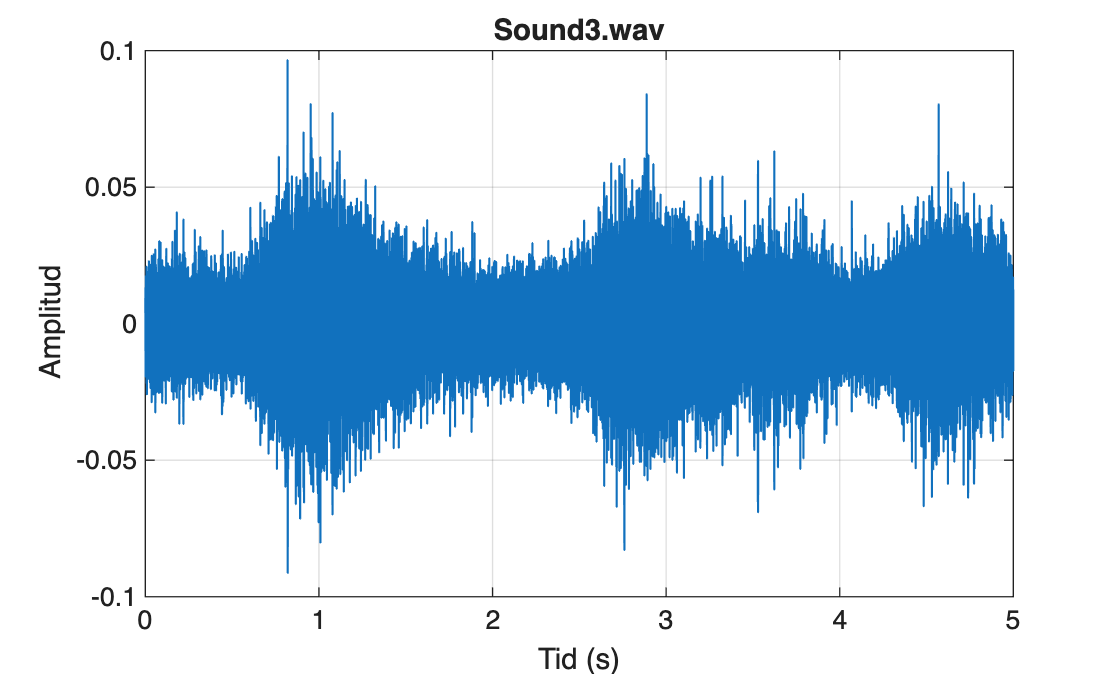

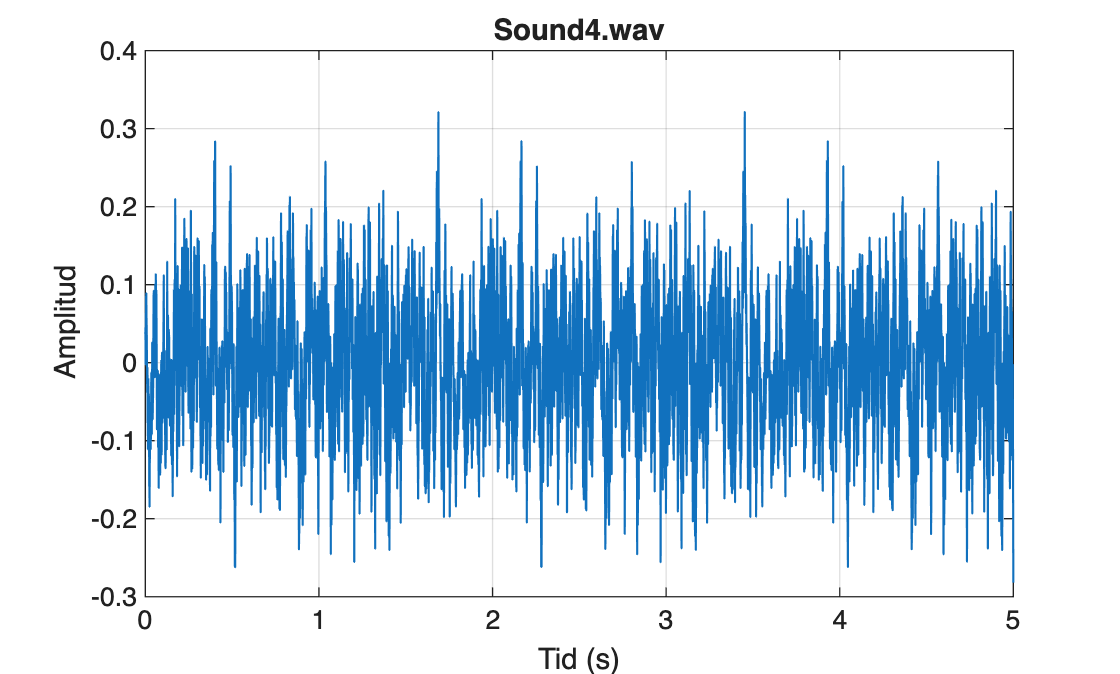

% add your code here
files = {'Sound1.wav', 'Sound2.wav', 'Sound3.wav', 'Sound4.wav'};

for i = 1:length(files) % for-loop så man ser alla plots. orka göra en för en.
    [y, Fs] = audioread(files{i}); % hela 1.1.1

    % Om signalen är stereo (två kanaler), ta genomsnittet eller en kanal
    if size(y, 2) > 1
        y = mean(y, 2);
    end
    
    t = (0:length(y)-1) / Fs; % ta fram hur lång tiden som ska visas
    figure(i)    
    plot(t, y, 'LineWidth', 0.8);
    title(strrep(files{i}, '_', '\_'), 'Interpreter', 'tex');
    xlabel('Tid (s)');
    ylabel('Amplitud');
    grid on;
end

***ANSWER: ***

Random: Sound 3

Deterministic: Sound 4

Periodic: Sound 2

Transient: Sound 1

## 1.2. Time histories, calculate different properties of the signal

Do the following analysis on one of the signals Sound1-Sound4. If your surname (family name) starts with A-F use Sound1, G-L use Sound2, M-R use Sound3, S-Ö use Sound4. If the sound is a stereo signal (have two channels) report the calculations below separately for each channel. If you cooperate you choose one of the optional signals for the entire group.

% load your relevant signal here
[y, Fs] = audioread("Sound4.wav");

### 1.2.1.     Calculate the root mean squared (r.m.s.) value by using the predefined `MATLAB` function for computing standard deviations

% add your code here
r_m_s = rms(y);

***ANSWER: [0.594043827605414]***

### 1.2.2.     Calculate the peak value, the peak-to-peak value and the crest factor for the signals using `MATLAB’s` predefined functions 

% add your code here
pektopek = peak2peak(y);
crestfactor = max(abs(y))/r_m_s

crestfactor = 3.6784

***ANSWER: 0.594043827605414 ****och *`3.6784`

## 1.3. Amplitude probability density functions

Load the file “Bearing.mat” that contains two signals of rotating machinery. One of the signals contains a faulty bearing and one is from a healthy machine.

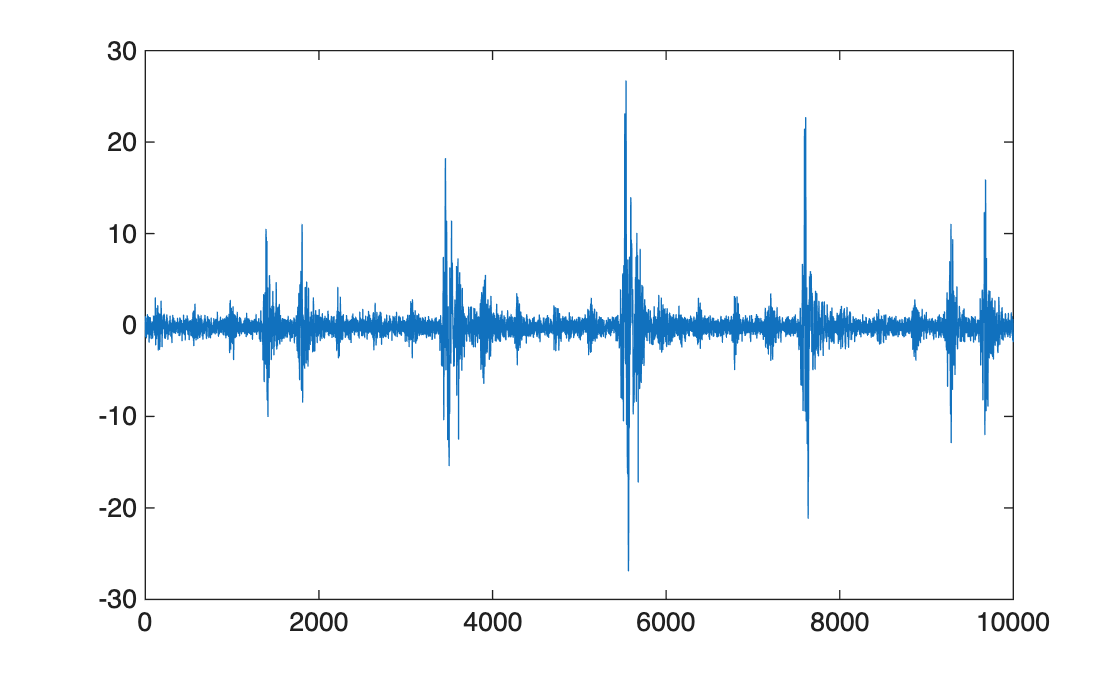

% load and plot the time signals here
load("Bearing.mat")
plot(linspace(0,9999,10000), Bearing1);

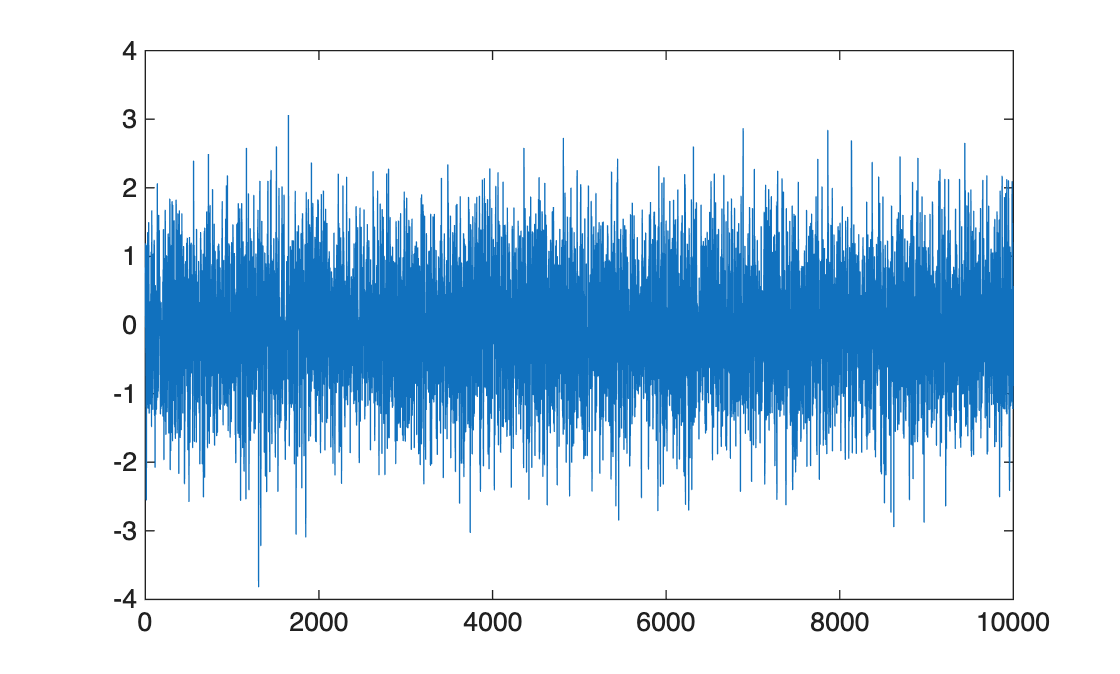

plot(linspace(0,9999,10000), Bearing2);

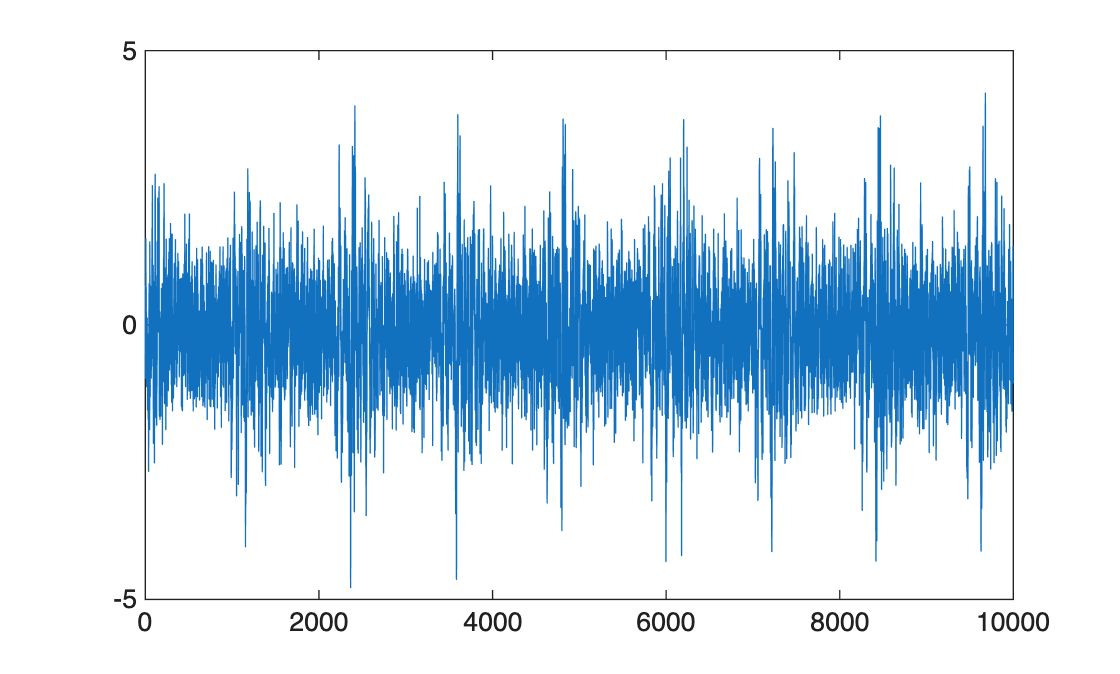

plot(linspace(0,9999,10000), Bearing3);

### 1.3.1.     Calculate the probability density functions for the signals in `MATLAB` using the histogram “`hist`” command 

Plot the probability density functions as bar plots with at least 20 segments. What is the value of the peak in the plot? Verify that the total probability is one.

% plot histogram functions here
xbins = 20

xbins = 20

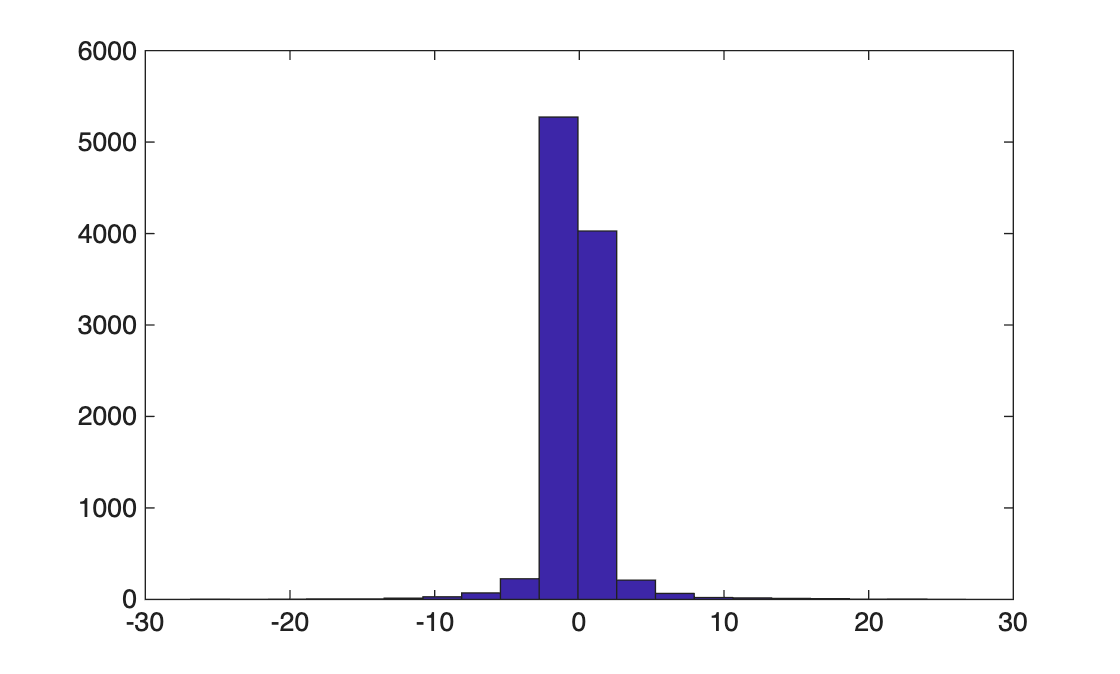

hist(Bearing1,xbins);

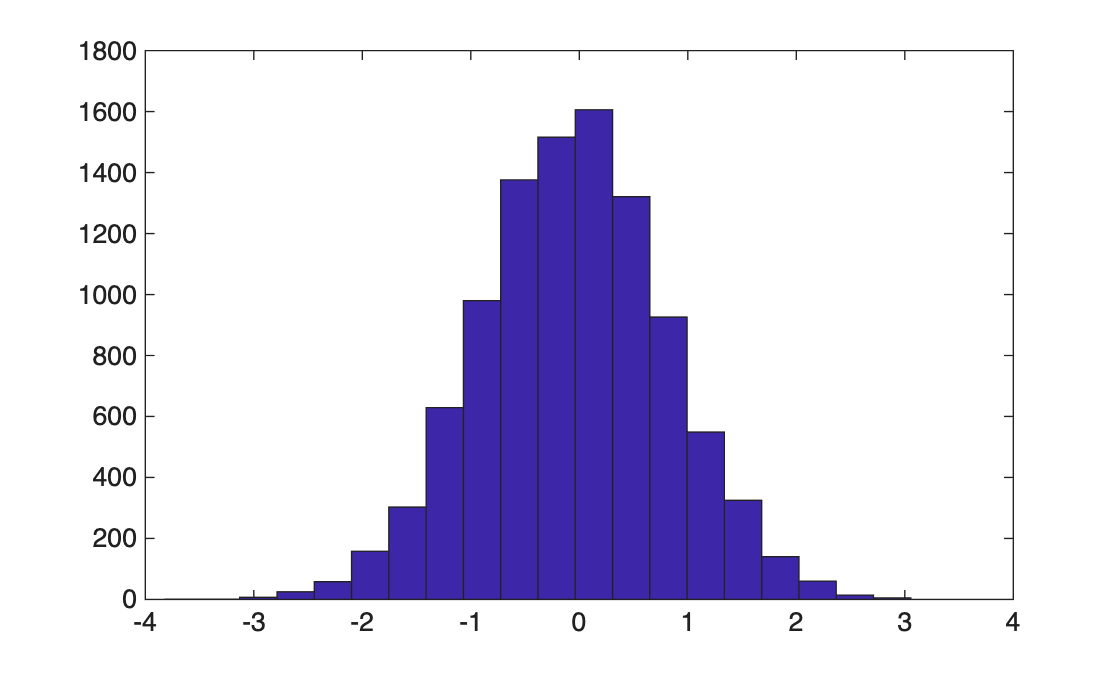

max(hist(Bearing1,xbins));
hist(Bearing2,xbins);

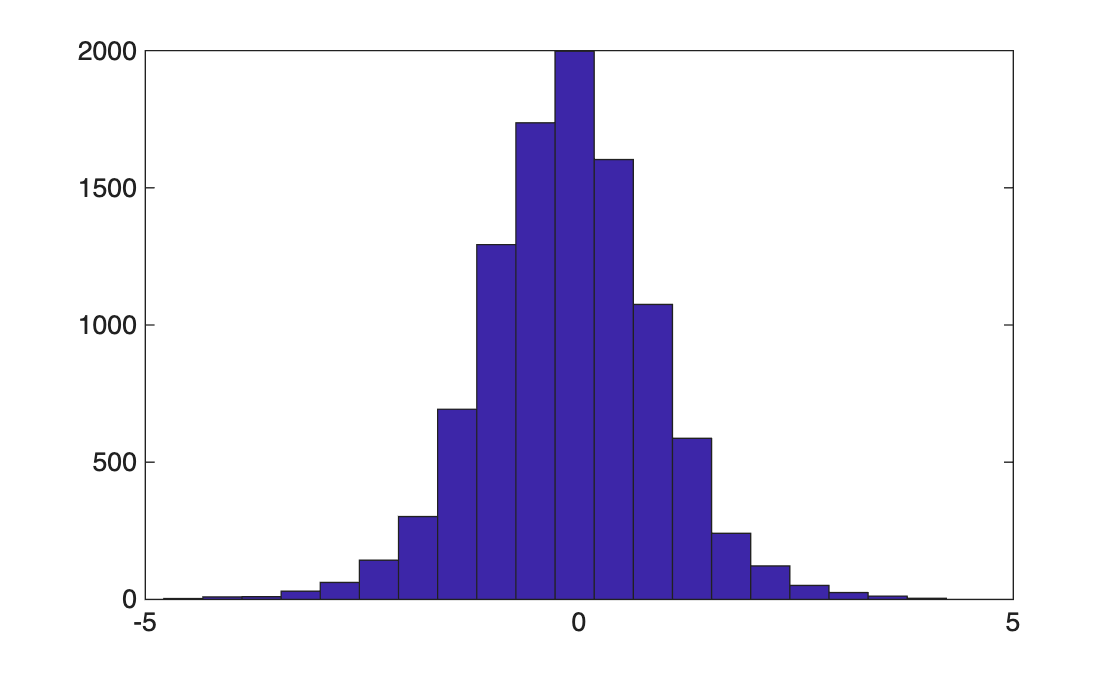

max(hist(Bearing2,xbins));

hist(Bearing3,xbins);

max(hist(Bearing3,xbins));

***ANSWER: ***`5274, 1606, 1998`

### 1.3.2.     Calculate the skewness and kurtosis of the signals 

From these quantities determine which of the bearings you suspect is faulty. Describe how you reached your conclusion.

% add your code here
skewness(Bearing1)

ans = 0.3760

skewness(Bearing2)

ans = -0.0214

skewness(Bearing3)

ans = -0.0032

kurtosis(Bearing1)

ans = 42.4837

kurtosis(Bearing2)

ans = 3.0316

kurtosis(Bearing3)

ans = 3.9356

***ANSWER: Bearing 1 should be the faulty one. Its kurtosis is much higher than the others.***

# 2: CONVOLUTION

## 2.1.     Compute convolutions with a given impulse response

Calculate and plot the output signals in time domain, `y`, for the following inputs: 

`x``1``=[0 1 0 0 0 0]``'` , `x``2``=[0 1 0 0 1 0]``'`  and `x``3``=2*sin(``(0:0.1:2*pi)'``),` and a system response  `h=[-1 1 3 5 3 1 -1 -3]'`. Hint: use a discrete convolution to perform this operation:                  


$$y[n] = \sum_{i=0}^n x[i] h[n-i]$$
           

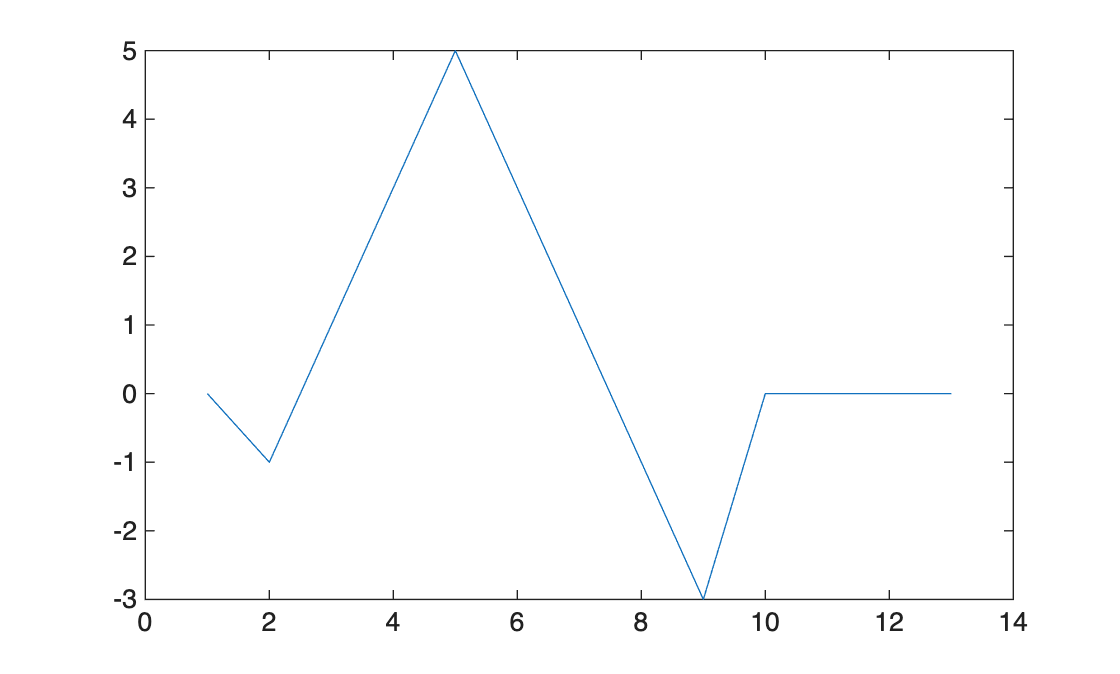

% compute convolutions here
x1=[0 1 0 0 0 0]';
x2=[0 1 0 0 1 0]';
x3=2*sin((0:0.1:2*pi)');
h=[-1 1 3 5 3 1 -1 -3]';

y1 = conv(x1, h);
y2 = conv(x2, h);
y3 = conv(x3, h);
figure()
plot(y1)

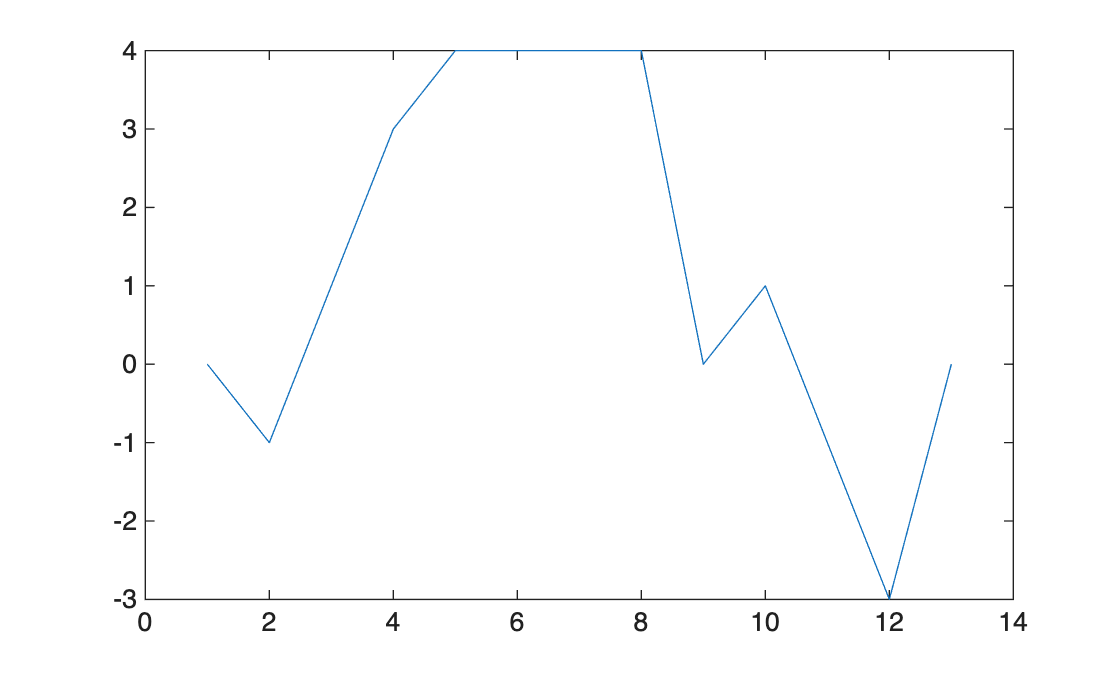

figure()
plot(y2)

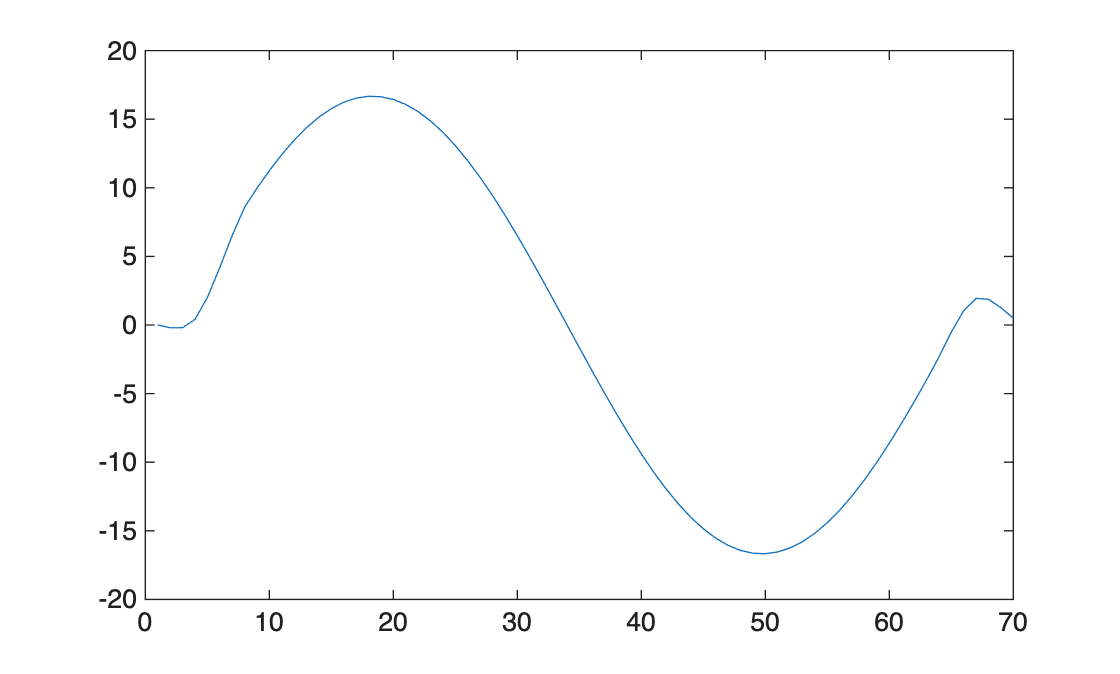

figure()
plot(y3)

### 2.1.1.     Explain how `x` and `h` are producing the output `y` for the inputs `x``1,` `x``2, and x3`

***ANSWER: ****< Add your answer here >*

### 2.1.2.     Use a different system `h` that you specify by yourself (choose amplification and length) 

Plot the output from the system using input `x``1`. 

% add your code here and plot
t = linspace(0,2*pi,10*length(h));
h2 = 6*exp(-2*t).*sin(t);

y_h2 = conv(x1, h2)'

y_h2 =          0
         0
    0.4066
    0.6914
    0.8799
    0.9933
    1.0489
    1.0611
    1.0412
    0.9987
    0.9407
    0.8731
    0.8004
    0.7258
    0.6520


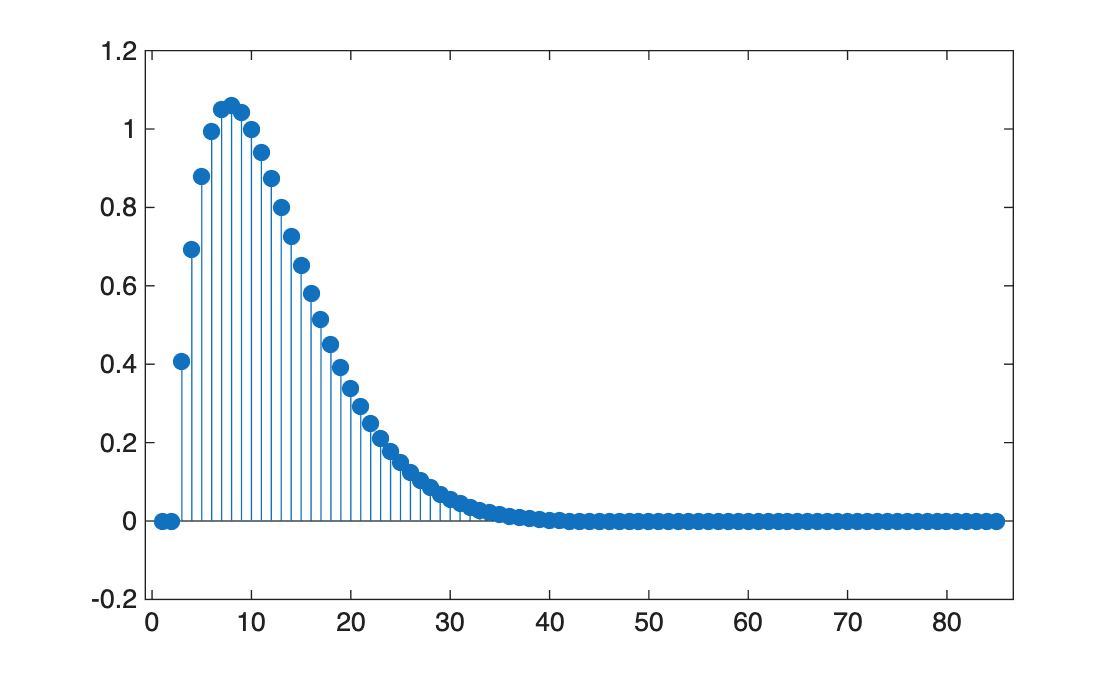

stem(y_h2, 'filled');

### 2.1.3.     Are the above mentioned systems in 2.1 & 2.2 linear and time invariant? Motivate your answer

***ANSWER: Discrete convolution is linear and time invariant and therefore the systems which use discrete convolution are linear and time invariant.***

## 2.2.     Convolutions applied to a truck suspension system 

A truck suspension system is described by a 1-DOF mass spring damper system and has an impulse response function as a function of time, *t*: 

### 
$$h(t) = sin(100t)e^{-nt}$$


where *n = 5**. *

### **2.2.1.     Show the output of this system in time domain using an impulse input at 100 ms time and a time vector with ∆*****t *****= 1 ms **

Show graphs of both inputs and all three quantities, *x(t), h(t), *and* y(t), *using the stem command and interpret the output.

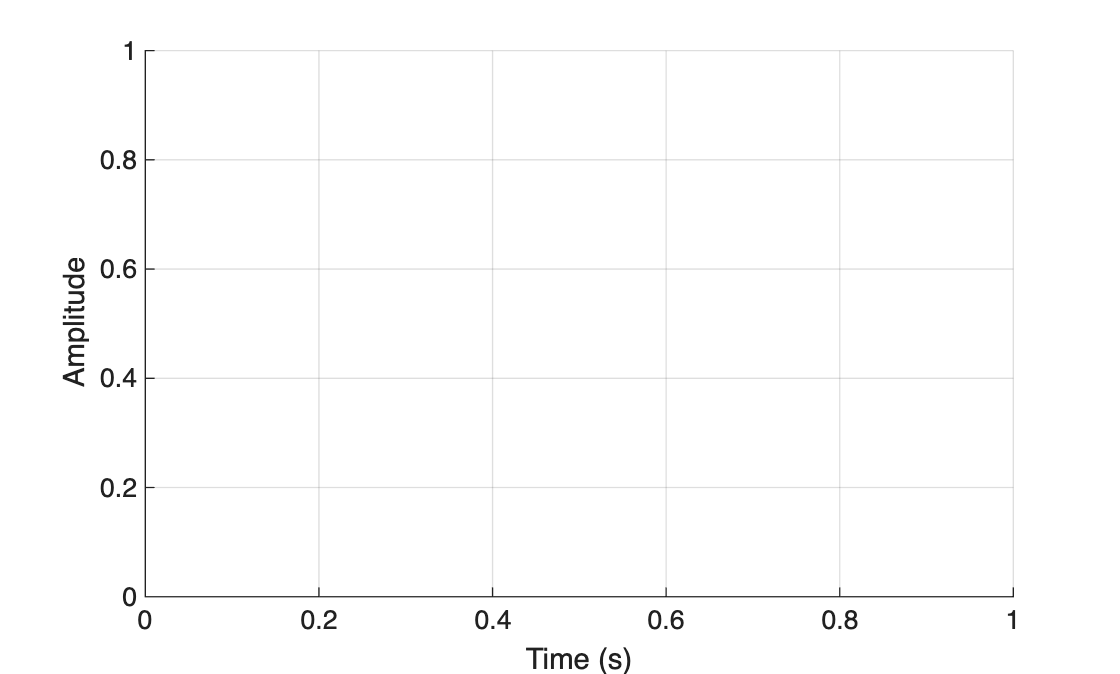

% add your relevant code and plots here
t = linspace(0, 0.1, 0.001);
n = 5;
h = sin(100*t) .* exp(-n*t);
x = 2*sin(t); % assume x is the same as x3 from before.
y_t = conv(x,h);

figure;
plot(t, h, 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

figure;
plot(t, x);
figure;
plot(t, y_t(1:length(t)));


***ANSWER: ****< Add your answer here >*

### **2.2.2.     Increase the system's damping to *****n = 50***** and use the same input as with *****n = 5*** 

Show graphs all three quantities, *x(t), h(t), *and* y(t), *using the stem command and compare the outputs between *n = 5 *and* n = 50*. What kind of output would be observed if *n = *-*5 *?  

% add your relevant code and plots here
n = 50;
h = sin(100*t) .* exp(-n*t);
figure;
plot(t, h, 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;



n = -5;
h = sin(100*t) .* exp(-n*t);
figure;
plot(t, h, 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

***ANSWER: ****< Add your answer here >*

# 3: DISCRETE SIGNALS IN TIME DOMAIN

## 3.1. Discrete amplitudes (a.k.a. quantization)

### 3.1.1.    Checkup questions

Read [Chapter 5.2](https://canvas.kth.se/courses/58301/files/folder/Course%20book?preview=9651035) in the course compendium and answer the following questions: 

- For industrial applications with smaller digital computers (for instance RaspberryPi) or multiple parallel processes, low bit sizes are preferred to help with memory usage and processor capability. How many digital steps are available for an 8-bit system? 

***            ANSWER: ****< Add your answer here > *

*256 digital steps. 2^8. It goes from 0 to 255.*

- What dynamic range (in dB) would the 8-bits above correspond to?

***            ANSWER: ****< Add your answer here >*

- (Answer not in course compendium) What is the default bit size in `MATLAB`?

***            ANSWER: ****< Add your answer here >*

*64-bit*

### **3.1.2.    Use the **`audioread`** command to read the file "Classic.wav"**

What is the number of bits in the data (single or double)?

% add relevant code here 
[y, Fs] = audioread("Classic.wav");


***ANSWER: ****< Add your answer here >*

Now, quantize the signal by using Nbits = 8 and 16 using the commands: 

Finally, listen (preferrably in headphones) to the original and the two downsampled signals.

% add relevant code here
nBits = 16;
y_nBits = round(y * 2^(nBits-1)-1) / (2^(nBits-1)-1);     % nBits signed quantization
sound(y_nBits, Fs);

Comment on if you can hear differences. 

***ANSWER: ****< Add your answer here >*

Extra question: Which composer do you think it is?

***ANSWER: ****< Add your answer here >*

### **3.1.3.    Use the **`audioread`** command to read the file "Acid.wav" **

Plot the data in time domain and quantize and listen to it using as in Section 3.1.2 with 16 and 8 bits

% add your code and plot here
[y_acid, Fs_acid] = audioread("Acid.wav");

Comment on if you hear any differences and compare the dynamic range to the Classical tune, is it higher or lower than for the modern music?

***ANSWER: ****< Add your answer here >*

## 3.2. Discrete time steps (a.k.a. sampling)

Create a sinusoid signal with 10 Hz oscillations as follows: 

### **3.2.1.    Plot the time series **`x`** with correct x- and y-axis**

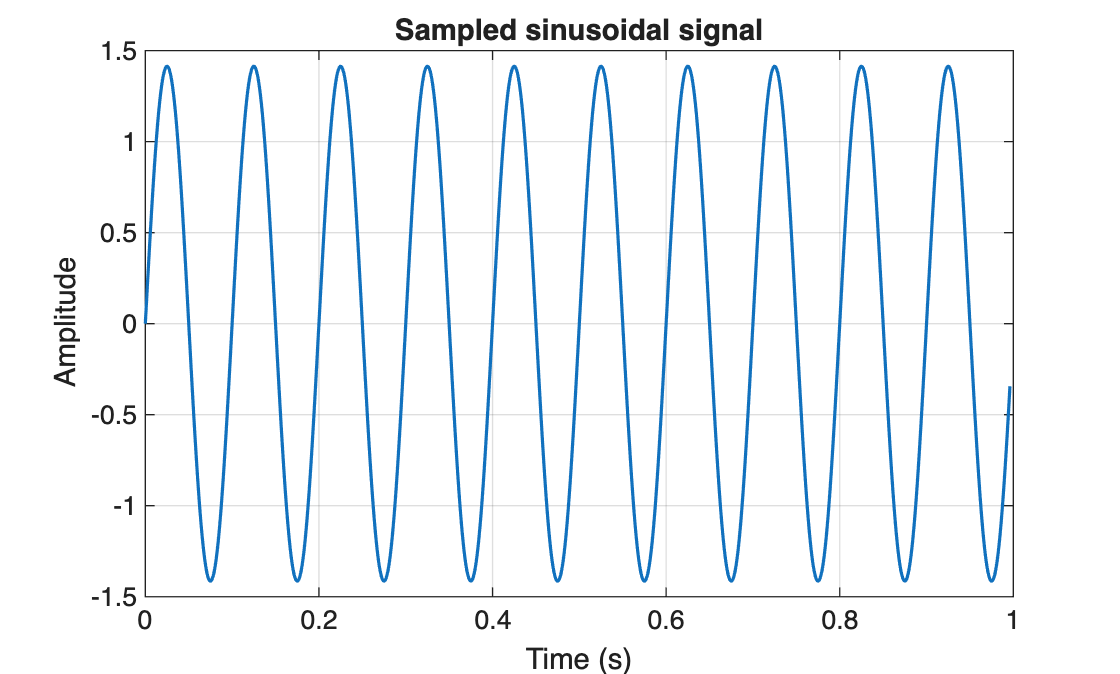

% add your plot here
freq = 10;
delta_t= 1 / 1024;
t = 0:delta_t:1-4*delta_t;
x = sqrt(2)*sin(2*pi*freq*t);
figure;
plot(t, x, 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Sampled sinusoidal signal');
grid on;

### **3.2.2.    Resample the signal with the following time steps 1/15, 1/20, 1/40, 1/80, 1/160 seconds **

Plot the sampled signals and the original in the same graph. 

% add your code and plots here
resample = [1/15, 1/20, 1/40, 1/80, 1/160]

for i = 1:length(resample)
    
end

Compare the sampled signals to the original, when are the sampled signals and original signal sufficiently similar? 

***ANSWER: ****< Add your answer here >*

### **3.2.3.    Reuse the signal from 3.1.3. ("Acid.wav") and resample it at every 4th and 128th points **

Plot the resampled signals in the same graph as the original sample either using comma notation `x_resamp4 = x(1:step:end)` or `resample` in `MATLAB`. 

% add your code and plots here


Describe the difference between the three sample rates by zooming in on a short time segment. 

***ANSWER: ****< Add your answer here >*

# 4: CORRELATION

## 4.1. Correlations of bursting balloons

Correlation analyses are used to assess linear relationships with respect to time delays between itself (auto-correlation) and two signals (cross-correlations). In this section you will evaluate echoes of three recordings of bursting balloons. The recordings are in stereo, but you should study only one channel, choose any data set. 

### **4.1.1.    Evaluate the auto-correlation of the anechoic recording of the bursting balloon ("Balloon_anechoic.wav") **

Read and plot the audio file as usual and save the sampling frequency. 

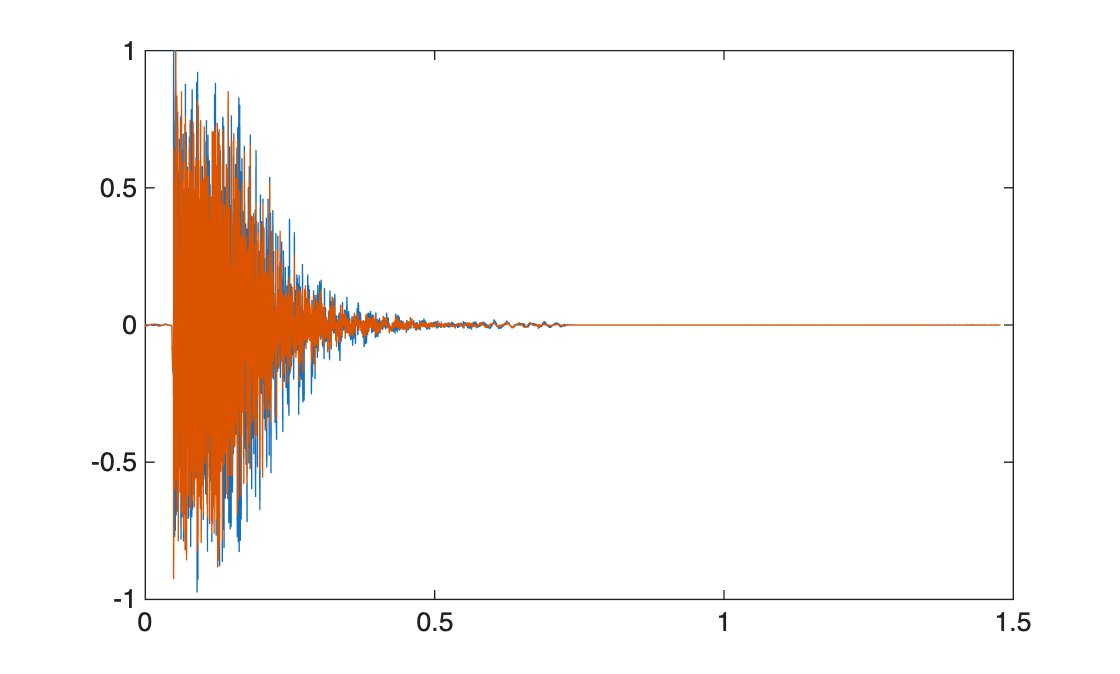

% add your code and plot here
[yBalloon, Fs] = audioread("Balloon_anechoic.wav");

plot((0:length(yBalloon)-1) / Fs, yBalloon);

sound(yBalloon, Fs);

Interpret if the burst can be assumed a periodic or a random signal.

***ANSWER: ****< Add your answer here >*

Use the command `“xcorr” `and plot the output with correct scaling on the x-axis. **A common error is to use the index 1, 2, 3, ..., N on the x- axis which is incorrect and results in mandatory correction and resubmission of the report**. Hint: The time steps on the x-axis can be calculated from the sampling frequency and the total time of the entire sound. 

% add your code and plot here


### **4.1.2.    Listen to the wav-file "Balloon_echo.wav" and note that an echo occurs **

This is because the sound is reflected from a wall. Use correlation analysis as you did in Task 4.1.1. to assess the delay time $t_d$ of the echo and determine the distance to the wall $d$. Note that the travel time is back and forth so $d=ct_d/2$, where $c$ is the speed of sound in air, assumed to be 342 m/s. 

% add your code and plots here


***ANSWER: ****< Add your answer here >*

### 4.1.3.    Repeat Task 4.1.2 for the wav file "Balloon_echo_or_not.wav"

Do you hear any echo? Is the correlation analysis indicating that there is a reflectig surface and if so at what distance? Hint: Compare the correlations from the two earlier assignments to the output. 

% add your code and plots here


***ANSWER: ****< Add your answer here >*

## 4.2. (Extra non-mandatory) Correlation of images in 2D

Particle image velocimetry (PIV) is a method to determine fluid motions. It is used to obtain instantaneous [velocity](https://en.wikipedia.org/wiki/Velocity) measurements by using tracer [particles](https://en.wikipedia.org/wiki/Particle_%28ecology%29) which, for sufficiently small particles, are assumed to faithfully follow the [flow](https://en.wikipedia.org/wiki/Fluid_dynamics)[dynamics](https://en.wikipedia.org/wiki/Dynamics_%28mechanics%29). The fluid with entrained particles is illuminated and photographed by a camera. The motion of the seeding particles is used to calculate the [velocity field](https://en.wikipedia.org/wiki/Vector_field) of the flow being studied.

In this task, you will find out the velocity of the fluid field in the images “Correlation_2D_1.jpg” and “Correlation_2D_2.jpg” provided the sampling interval ∆t = 0.2 s and the pixel size is 1 mm. 

To read the images use the commando `“imread”`and transform the color images to black and white equivalents.  

% load the images here


### **4.2.1.     Calculate the auto-correlation of the two images separately **

Use the function `“xcorr2” `to compute 2D correlation of the two images. Be aware of how the output data is sorted. Plot the results using the command `“mesh”`. Do you detect any periodicity in the images or are the particles randomly distributed? Explain how you reached your conclusion.

% add your code and plots here


***ANSWER: ****< Add your answer here >*

### 4.2.2.     Calculate the cross correlation of the two images

Plot these results using the command `“mesh”` and calculate the velocity (x- and y-components) of the fluid. 

% add your code and plots here


***ANSWER: ****< Add your answer here >*